# MATLAB ASSIGNMENT-5

BL.AI.U4AID25064

Sudarshan Rao

Lab Exercise - 5

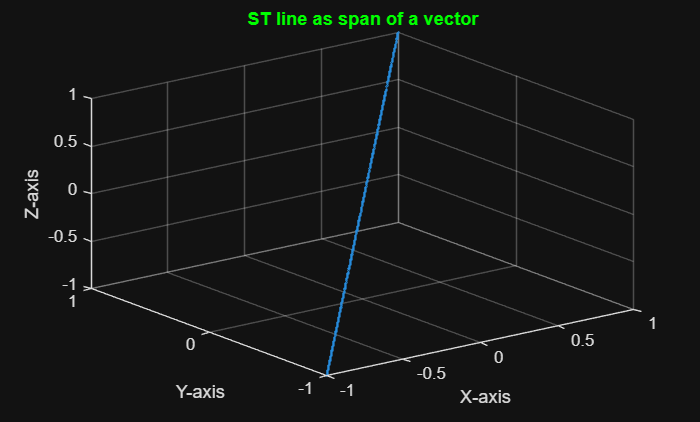

b=[1;1;1];
pts=[];
for i=1:1000
    k1=-1+2*rand(1);
    pts=[pts,k1*b];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('ST line as span of a vector','Color','green');

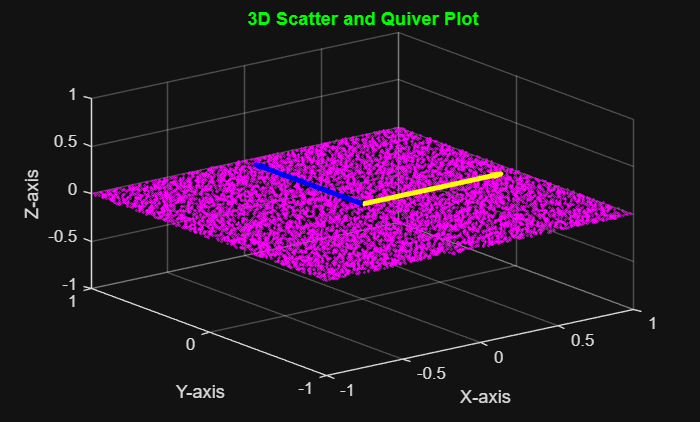

b1=[1;0;0];
b2=[0;1;0];
pts=[];
for i=1:10000
    k1=-1+2*rand(1);
    k2=-1+2*rand(1);
    pts=[pts,k1*b1+k2*b2];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1,'magenta');
hold on
quiver3(0,0,0,1,0,0,'y','LineWidth',3)
quiver3(0,0,0,0,1,0,'B','LineWidth',3)
hold off
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Scatter and Quiver Plot','Color','green');

A=randi([0,9],5,2)*randi([0,9],2,5)
[RR,ic]=rref(A)
r=length(ic)

r = 2

R_2=RR(1:r,:)
C_2=A(:,ic)
N=null(A)
S=size(N)
Nullity=S(:,2)

Nullity = 3

A1=randi([0,9],5,2)*randi([0,9],2,5)
[RR1,ic1]=rref(A1)
r1=length(ic1)

r1 = 2

R1=RR1(1:r1,:)
S1=size(A1)
NC=S1(:,2)

NC = 5

Nulity=NC-rank(A1)

Nulity = 3

B=A'
[RR_1,ic_1]=rref(B)
r_1=length(ic_1)

r_1 = 2

R_1=RR_1(1:r_1,:)  %Basis for Column space for A is same as Basis for row space of A'.
N_1=null(B)
S_1=size(N_1)
Nullity_1=S_1(:,2)

Nullity_1 = 3


S_2=size(B)
NC_2=S_2(:,2)

NC_2 = 5

Nullity_2=NC_2-rank(B)

Nullity_2 = 3

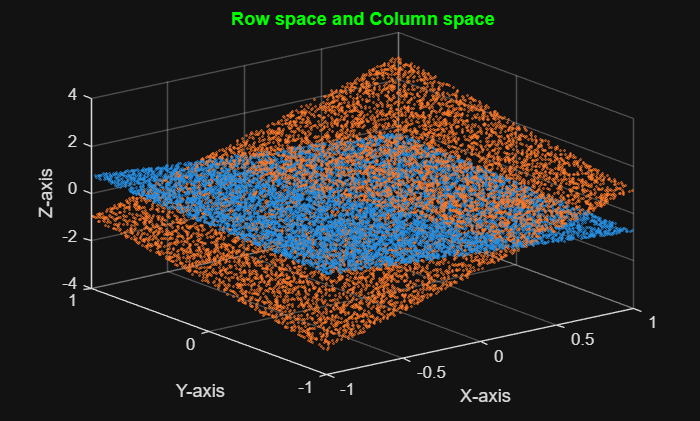

clf
a=randi([-3,3],3,2)*randi([-3,3],2,3)
[RR,ic]=rref(a);
r=length(ic);
R=RR(1:r,:);
RSB1=(R(1,:))';
RSB2=(R(2,:))';
[RR,ic]=rref(a');
r=length(ic);
C=RR(1:r,:);
CSB1=(C(1,:))';
CSB2=(C(2,:))';
n_pts=10000;
Pts_1=zeros(3,n_pts);
Pts_2=zeros(3,n_pts);
for i=1:n_pts
    a1=-1+2*rand(1);
    a2=-1+2*rand(1);
    b1=-1+2*rand(1);
    b2=-1+2*rand(1);
    Pts_1(:,i)=a1*RSB1+a2*RSB2;
    Pts_2(:,i)=b1*CSB1+b2*CSB2;
end
scatter3(Pts_1(1,:),Pts_1(2,:),Pts_1(3,:),1,'color','blue')
hold on
scatter3(Pts_2(1,:),Pts_2(2,:),Pts_2(3,:),1,'color','red')
hold off
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Row space and Column space','Color','green');
grid on

This is my Practise Assignment.

#### 1Q)

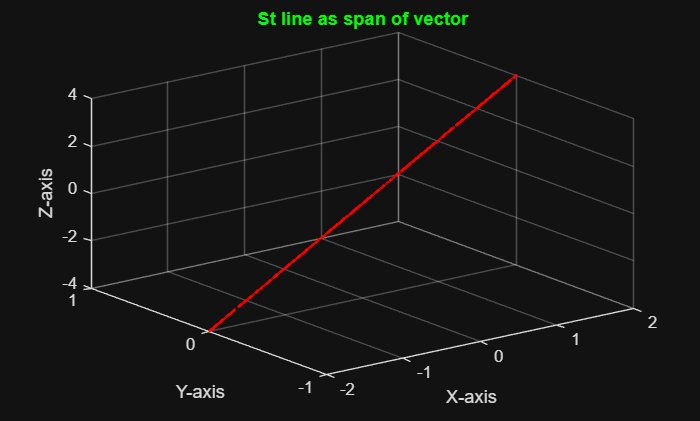

clf
b1_1=[1;0;2];
pts=[];
for i=1:1000
    k1_1=-2+4*rand(1);
    pts=[pts,k1_1*b1_1];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1,'red');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('St line as span of vector','Color','green');

#### 2Q)

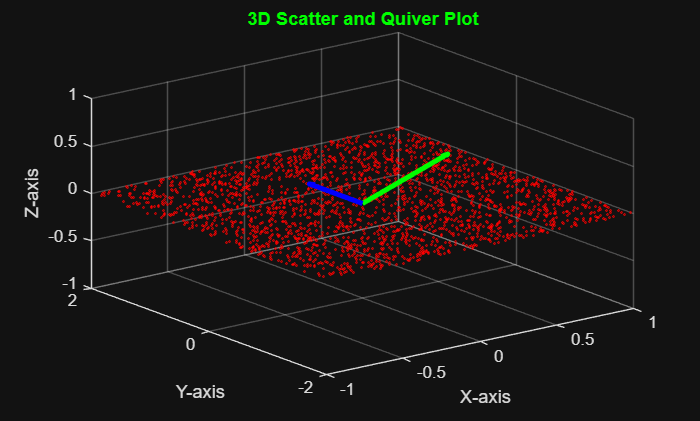

b2_1=[1;1;0];
b2_2=[0;1;0];
pts=[];
for i=1:10000
    k2_1=-3+6*rand(1);
    k2_2=-3+6*rand(1);
    pts=[pts,k2_1*b2_1+k2_2*b2_2];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1,'red')
hold on
quiver3(0,0,0,b2_1(1),b2_1(2),b2_1(3),'g','linewidth',3)
quiver3(0,0,0,b2_2(1),b2_2(2),b2_2(3),'b','LineWidth',3)
hold off
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Scatter and Quiver Plot','Color','green');
grid on;
axis([-1 1 -2 2 -1 1])

#### Yes, the given set of basis vectors span the XY plane, i.e, z=0.

#### 3Q)

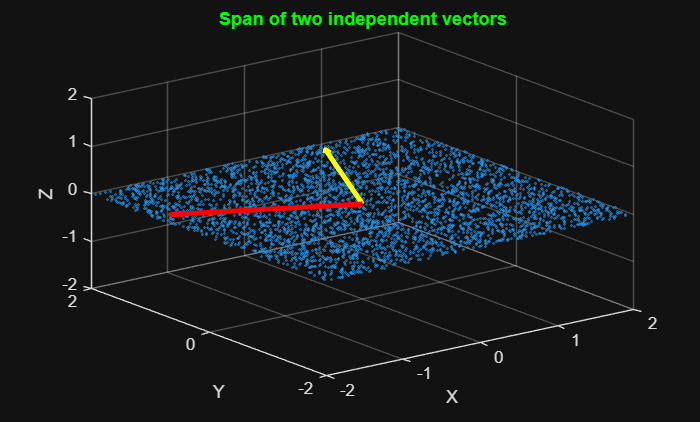

b3_1=[1;2;0];
b3_2=[-2;1;0];
num_pts=20000;
pts=zeros(3,num_pts);
for i=1:num_pts
    k3_1 = -2+4*rand(1);
    k3_2 = -2+4*rand(1);
    pts(:,i) = k3_1 * b3_1 + k3_2 * b3_2;
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1,'Color','blue')
hold on
quiver3(0,0,0,1,2,0,'Color','yellow','LineWidth',3)
quiver3(0,0,0,-2,1,0,'Color','red','LineWidth',3)
hold off
axis([-2 2 -2 2 -2 2])
xlabel('X')
ylabel('Y')
zlabel('Z')
title('Span of two independent vectors','Color','green')

4Q)

clf
M=[1 0 0;0 0 0;0 0 3];
N=null(M)
[RR,ic]=rref(M)
r=length(ic)

r = 2

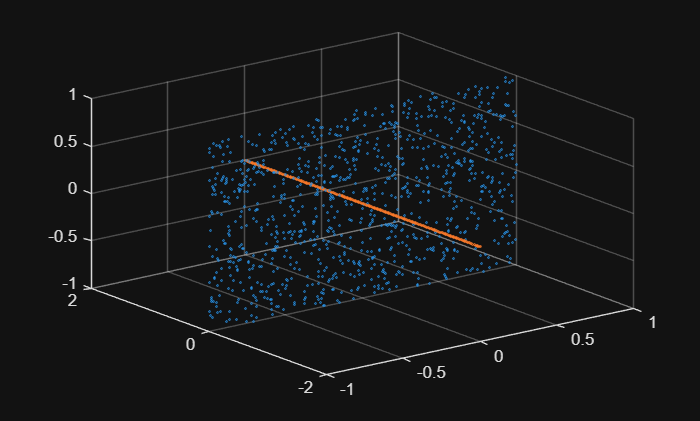

RC=RR(1:r,:)
RSB1=(RC(1,:))'; RSB2=(RC(2,:))';
RSpts=zeros(3,1000);
NSpts=zeros(3,1000);
for i=1:1000
    k4_1=-1+2*rand(1);
    k4_2=-1+2*rand(1);
    k4_3=-2+4*rand(1);
    RSpts(:,i)=k4_1*RSB1+k4_2*RSB2;
    NSpts(:,i) = k4_3 * N(:,1);
end
scatter3(RSpts(1,:),RSpts(2,:),RSpts(3,:),1,'Color','blue')
hold on
scatter3(NSpts(1,:),NSpts(2,:),NSpts(3,:),1,'Color','green')

5Q)

clear
clf
A=[1 4;0 5];  %As rank=n; null space will be Origin only. Hence, no basis vectors for 1 point
B=[0 0;0 5];
C=zeros(2);
nuA=null(A)


nuA =

  2×0 empty double matrix



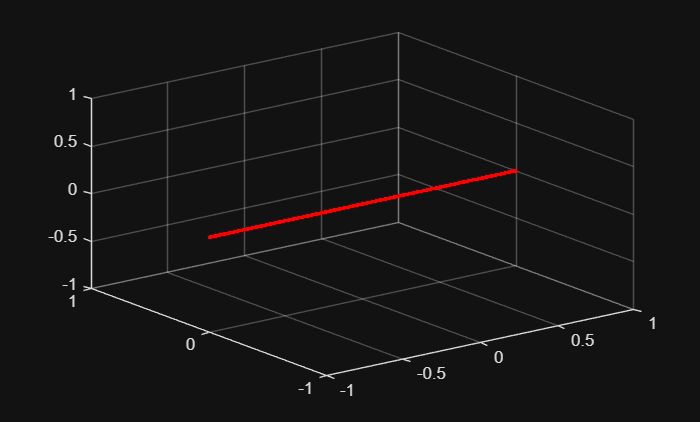

nuB=null(B)
nuC=null(C)
NSptsB=zeros(2,1000);
for i=1:1000
    k5_2=-1+2*rand(1);
    NSptsB(:,i) = k5_2 * nuB(:,1);
end
scatter3(NSptsB(1,:),NSptsB(2,:),0,36,"r.")

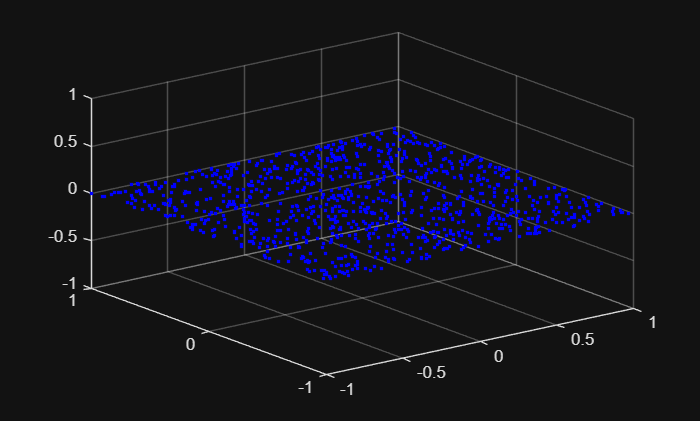

NSptsC=zeros(2,1000);
for i=1:1000
    k5_31=-1+2*rand(1);
    k5_32=-1+2*rand(1);
    NSptsC(:,i) = k5_31 * nuC(:,1)+k5_32*nuC(:,2);
end
scatter3(NSptsC(1,:),NSptsC(2,:),0,36,"b.")

6Q)

clear
A=randi([0,3],3,2)*randi([0,3],2,3)

rank(A)

ans = 2

clf
[RR,ic]=rref(A)
r=length(ic)

r = 2

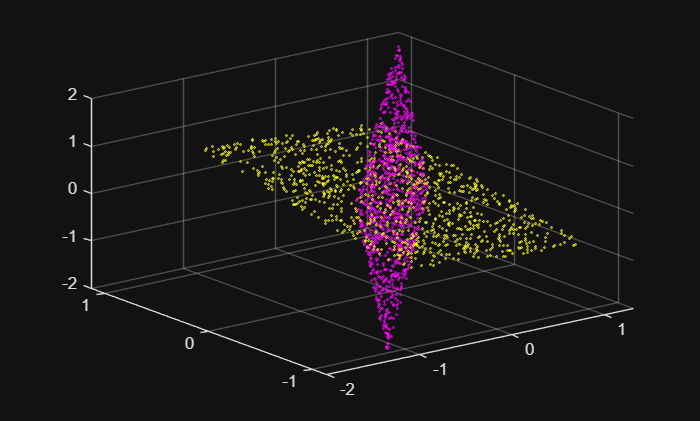

RS=RR(1:r,:)
RSpts=zeros(3,1000);
for i=1:1000
    k6_1=-1+2*rand(1);
    k6_2=-1+2*rand(1);
    RSpts(:,i)=k6_1*(RS(1,:))'+k6_2*(RS(2,:))';
end
scatter3(RSpts(1,:),RSpts(2,:),RSpts(3,:),1,'yellow')
hold on
CS=A(:,ic)
CSpts=zeros(3,1000);
for j=1:1000
    k6_3=-1+2*rand(1);
    k6_4=-1+2*rand(1);
    CSpts(:,j)=(k6_3*CS(:,1)+k6_4*CS(:,2))/10;
end
scatter3(CSpts(1,:),CSpts(2,:),CSpts(3,:),1,'magenta')
hold off

7Q)

clear
A=randi([0 3],3,1)*randi([0 3],1,3)

[RR1,ic]=rref(A)

ic = 1

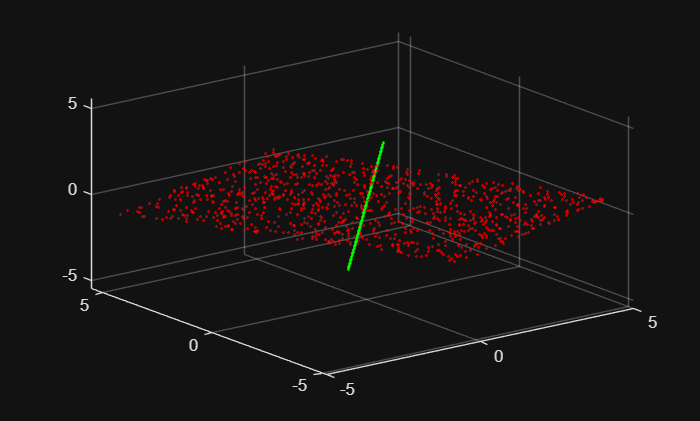

CS=A(:,ic)
CSpts=zeros(3,1000);
for i=1:1000
    k7=-1+2*rand(1);
    CSpts(:,i) = k7 * CS(:,1);
end
scatter3(CSpts(1,:),CSpts(2,:),CSpts(3,:),1,'green')
hold on
nuAt=null(A')
LNSpts=zeros(3,1000);
for i=1:1000
    k7_1=-5+10*rand(1);
    k7_2=-5+10*rand(1);
    LNSpts(:,i) = k7_1 * nuAt(:,1)+k7_2*nuAt(:,2);
end
scatter3(LNSpts(1,:),LNSpts(2,:),LNSpts(3,:),1,'red')
hold off

8Q)

clear
A8=[1 3 4 7;2 4 6 10;3 5 8 13;4 6 10 16]
rankA8=rank(A8)

rankA8 = 2

u=[-2 -3 1 1]';v=[5 8 11 14]';w=[1 1 2 3]';y=[1 2 0 -1]';m=[-1 1 1 -1]';
rank([A8,u])

ans = 3

rank([A8;u'])

ans = 3

A8*u
u'*A8
%vector u lies in null space of matrix A
rank([A8,v])

ans = 2

rank([A8;v'])

ans = 3

A8*v
v'*A8
%vector v lies in column space of matrix A
rank([A8,w])

ans = 3

rank([A8;w'])

ans = 2

A8*w
w'*A8
%vector w lies in row space of matrix A
rank([A8,y])

ans = 3

rank([A8;y'])

ans = 3

A8*y
y'*A8
%vector y lies in null space of matrix A
rank([A8,m])

ans = 3

rank([A8;m'])

ans = 3

A8*m
m'*A8
%vector m lies in left null space of matrix A

9Q)

clear
A9=[1 -1 2 3;0 2 1 4;1 1 3 1;2 0 5 4]
rankA9=rank(A9)

rankA9 = 3

v1=[5 1 -2 0]';w1=[0 2 2 2]';u1=[-1 2 -1 1]';m1=[3 -1 7 7]';
rank([A9,v1])

ans = 4

rank([A9;v1'])

ans = 4

A9*v1
v1'*A9
%vector v lies in null space of matrix A
rank([A9,w1])

ans = 3

rank([A9;w1'])

ans = 4

A9*w1
w1'*A9

ans = 1×4
     6     6    18    18


%vector w lies in column space of matrix A
rank([A9,u1])

ans = 4

rank([A9;u1'])

ans = 4

A9*u1

ans = 4×1
    -2
     7
    -1
    -3


u1'*A9

ans = 1×4
     0     4     2     8


%vector u does not lie in any of the subspaces of matrix A
rank([A9,m1])

ans = 4

rank([A9;m1'])

ans = 3

A9*m1

ans = 4×1
    39
    33
    30
    69


m1'*A9

ans = 1×4
    24     2    61    40


%vector u lies in row space of matrix A

10Q) 1)

clear
Aten=randi([0 3],9,2)*randi([0 3],2,9)

Aten = 9×9
     1     3     1     3     3     0     1     1     0
     3     9     3     3     6     9     3     6     6
     4    12     4     6     9     9     4     7     6
     3     9     3     7     8     3     3     4     2
     3     9     3     3     6     9     3     6     6
     2     6     2     2     4     6     2     4     4
     0     0     0     0     0     0     0     0     0
     6    18     6    12    15     9     6     9     6
     5    15     5    11    13     6     5     7     4


rankA10=rank(Aten)

rankA10 = 2

B=Aten+Aten'

B = 9×9
     2     6     5     6     6     2     1     7     5
     6    18    15    12    15    15     3    24    21
     5    15     8     9    12    11     4    13    11
     6    12     9    14    11     5     3    16    13
     6    15    12    11    12    13     3    21    19
     2    15    11     5    13    12     2    13    10
     1     3     4     3     3     2     0     6     5
     7    24    13    16    21    13     6    18    13
     5    21    11    13    19    10     5    13     8


rank(B)

ans = 4

[V,D]=eig(B);
%Loop for obtaining eigenvectors
for i=1:9
    V(:,i)
end

ans = 9×1
   -0.0078
    0.4518
   -0.0663
    0.1481
    0.4584
   -0.0586
    0.1701
   -0.4287
   -0.5859


ans = 9×1
    0.4043
    0.1081
   -0.6041
    0.1084
   -0.2601
    0.4322
    0.3722
   -0.1716
    0.1605


ans = 9×1
    0.0504
   -0.2392
   -0.1543
   -0.0548
    0.0324
    0.1553
    0.2034
    0.6853
   -0.6142


ans = 9×1
    0.7274
   -0.1034
    0.4065
   -0.4064
    0.0695
   -0.2053
    0.2737
   -0.0868
   -0.0203


ans = 9×1
   -0.3900
    0.3277
   -0.0321
   -0.2491
   -0.2093
   -0.3889
    0.6598
    0.1545
    0.1523


ans = 9×1
   -0.0867
   -0.0171
    0.5717
    0.3801
   -0.5435
    0.2927
    0.2251
   -0.1687
   -0.2463


ans = 9×1
    0.2466
    0.6130
   -0.0633
   -0.1157
   -0.4718
   -0.1771
   -0.4639
    0.2040
   -0.1880


ans = 9×1
    0.2541
   -0.1639
   -0.1345
    0.6957
   -0.0429
   -0.6222
    0.0749
    0.1028
    0.0365


ans = 9×1
    0.1408
    0.4538
    0.3028
    0.3071
    0.3909
    0.2968
    0.0973
    0.4528
    0.3645


%Loop for obtaining Eigenvalues
for i=1:9
    D(i,i)
end

ans = -15.9733

ans = -4.0445

ans = -1.3075e-14

ans = -5.4743e-16

ans = -3.0401e-16

ans = 5.2604e-16

ans = 1.5122e-15

ans = 9.8434

ans = 102.1744

%There are no complex eigenvalues because B is a symmetric matrix 
% and all symmetric matrices must have real eigenvalues as their complex
% conjugates are also equal to the original matrix B.

q=0;
for i=1:9
    q=q+D(i,i);
end
q

q = 92.0000

traceB=trace(B)

traceB = 92

j=1;
for i=1:9
    j=j*D(i,i);
end
j

j = -1.1246e-70

detB=det(B)

detB = 1.7404e-73

%Rank of the matrix will be equal to the number of non-zero eigenvalues
% 5 of the elements are very close to zero (of order 10^-16) and these were
% supposed to be zero but matrix calculations approximates the values close
% to zero.
%Sum of Rank of B and algebraic multiplicity of eigenvalue '0' will give
%the number of columns.
k=0;
for i=1:9
    for j=i:9
        if i~=j
            dot(V(:,i),V(:,j));
            k=k+1;
        end
    end
end
k

k = 36

%As the vectors are not perpendicular, therefore the eigenvectors are not orthogonal.
[RR,ic]=rref(B)

RR = 9×9
    1.0000         0         0         0   -1.0000    2.3333    0.3333    2.3333    3.3333
         0    1.0000         0         0    0.8333    0.5000    0.3333   -0.5000   -0.6667
         0         0    1.0000         0         0    0.6667   -0.3333    1.6667    1.6667
         0         0         0    1.0000    0.5000   -1.5000         0   -0.5000   -1.0000
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


ic = 1×4
     1     2     3     4


r=length(ic)

r = 4

RS=RR(1:r,:)

RS = 4×9
    1.0000         0         0         0   -1.0000    2.3333    0.3333    2.3333    3.3333
         0    1.0000         0         0    0.8333    0.5000    0.3333   -0.5000   -0.6667
         0         0    1.0000         0         0    0.6667   -0.3333    1.6667    1.6667
         0         0         0    1.0000    0.5000   -1.5000         0   -0.5000   -1.0000


for i=1:r
    (RS(i,:))'
end

ans = 9×1
    1.0000
         0
         0
         0
   -1.0000
    2.3333
    0.3333
    2.3333
    3.3333


ans = 9×1
         0
    1.0000
         0
         0
    0.8333
    0.5000
    0.3333
   -0.5000
   -0.6667


ans = 9×1
         0
         0
    1.0000
         0
         0
    0.6667
   -0.3333
    1.6667
    1.6667


ans = 9×1
         0
         0
         0
    1.0000
    0.5000
   -1.5000
         0
   -0.5000
   -1.0000


%Basis for row space
CS=B(:,ic)

CS = 9×4
     2     6     5     6
     6    18    15    12
     5    15     8     9
     6    12     9    14
     6    15    12    11
     2    15    11     5
     1     3     4     3
     7    24    13    16
     5    21    11    13


for i=ic
    B(:,i)
end

ans = 9×1
     2
     6
     5
     6
     6
     2
     1
     7
     5


ans = 9×1
     6
    18
    15
    12
    15
    15
     3
    24
    21


ans = 9×1
     5
    15
     8
     9
    12
    11
     4
    13
    11


ans = 9×1
     6
    12
     9
    14
    11
     5
     3
    16
    13


%Basis of column space of matrix B
nullB=null(B)

nullB = 9×5
   -0.8594    0.0234   -0.0532    0.0220    0.0980
    0.0781    0.5327   -0.0243   -0.5104    0.0221
   -0.3293   -0.1234   -0.2465   -0.0666   -0.5762
    0.2813   -0.4714   -0.1204   -0.2444   -0.1117
   -0.0679   -0.1978    0.4719    0.4840    0.2586
    0.0672   -0.5388   -0.1945   -0.0386    0.0196
    0.1900    0.2902   -0.2277    0.6122   -0.5201
    0.1242    0.2195   -0.4543    0.2447    0.4913
    0.0845    0.1282    0.6345   -0.0669   -0.2574


for i=1:5
    nullB(:,i)
end

ans = 9×1
   -0.8594
    0.0781
   -0.3293
    0.2813
   -0.0679
    0.0672
    0.1900
    0.1242
    0.0845


ans = 9×1
    0.0234
    0.5327
   -0.1234
   -0.4714
   -0.1978
   -0.5388
    0.2902
    0.2195
    0.1282


ans = 9×1
   -0.0532
   -0.0243
   -0.2465
   -0.1204
    0.4719
   -0.1945
   -0.2277
   -0.4543
    0.6345


ans = 9×1
    0.0220
   -0.5104
   -0.0666
   -0.2444
    0.4840
   -0.0386
    0.6122
    0.2447
   -0.0669


ans = 9×1
    0.0980
    0.0221
   -0.5762
   -0.1117
    0.2586
    0.0196
   -0.5201
    0.4913
   -0.2574


%Basis for null space of matrix B
Asize=size(Aten)

Asize = 1×2
     9     9


Bsize=size(B)

Bsize = 1×2
     9     9


Nullity_A=Asize(:,2)-rank(Aten)

Nullity_A = 7

Nullity_B=Bsize(:,2)-rank(B)

Nullity_B = 5

%Nullity of A and B are 7 and 5 respectively

11Q)

A11=randi([0 3],10,3)*randi([0 3],3,5)

A11 = 10×5
     0     3     1     1     6
     3     5     7     4    15
     2     0     4     2     4
     1     9     5     4    20
     3     5     9     6    18
     2     8     6     4    19
     1     5     3     2    11
     0     4     0     0     6
     2     5     5     3    13
     0     5     3     3    12


S1=A11*A11'

S1 = 10×10
    47   116    30   156   138   148    86    48   101    93
   116   324   102   399   391   389   222   110   273   238
    30   102    40   110   126   112    62    24    82    66
   156   399   110   523   477   500   289   156   344   312
   138   391   126   477   475   466   265   128   328   286
   148   389   112   500   466   481   277   146   333   298
    86   222    62   289   265   277   160    86   191   172
    48   110    24   156   128   146    86    52    98    92
   101   273    82   344   328   333   191    98   232   205
    93   238    66   312   286   298   172    92   205   187


S2=A11'*A11

S2 = 5×5
          32          70          86          54         202
          70         295         231         161         719
          86         231         251         165         637
          54         161         165         111         435
         202         719         637         435        1832


raS1=rank(S1)

raS1 = 3

raS2=rank(S2)

raS2 = 3

S1eigval=eig(S1)

S1eigval = 10×1
1.0e+03 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0031
    0.0551
    2.4628


S2eigval=eig(S2)

S2eigval = 5×1
1.0e+03 *

    0.0000
    0.0000
    0.0031
    0.0551
    2.4628


%The eigenvalues of 5x5 symmetric matrix are also present in 10x10
%symmetric matrix along with 5 other additional zero eigenvalues. since,
%both of them originated from same A11 matrix of rank 3, both of them only
%have 3 same eigenvalues, while the others are zero.
sizeA11=size(A11)

sizeA11 = 1×2
    10     5


nullity_A=sizeA11(:,2)-rank(A11)

nullity_A = 2

sizeS1=size(S1)

sizeS1 = 1×2
    10    10


Nullity_S1=sizeS1(:,2)-rank(S1)

Nullity_S1 = 7

sizeS2=size(S2)

sizeS2 = 1×2
     5     5


Nullity_S2=sizeS2(:,2)-rank(S2)

Nullity_S2 = 2